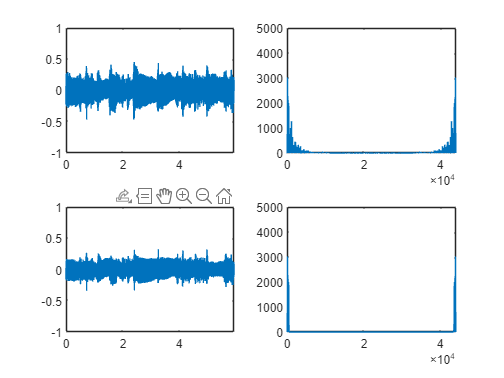

%read mp3 file
n = 1024*256;                   % number of samples to read
start = 500000;                 % first sample to read
finish = 500000 + n - 1;        % last sample to read
filename = 'guitar.wav';
[y,fs]=audioread(filename,[start,finish]); % read samples from start to finish
y1 = y(:,1);                    % take only 1 channel
ts = 1/fs;                      % sample time
f0 = fs/n;                      % frequency resolution
x=0:ts:(n-1)*ts;                % time axis
xf = 0:f0:(n-1)*f0;             % frequency axis

%define axes to plot time samples y1..y4 (4x2 axes, axes 1,3,5,7)
ay1 = subplot(2,2,1);
ay2 = subplot(2,2,3);
%define axes to plot spectra yf1..yf4 (4x2 axes, axes 2,4,6,8)
ay1f = subplot(2,2,2);
ay2f = subplot(2,2,4);

fCenter = 300;                         % frequency of extra component
fLow = fCenter-250;                     % low cut-off frequency
fHigh = fCenter+250;                    % High cut-off frequency
iCenter = round(fCenter/f0);            % index of center frequency
iLow = round(fLow/f0);                  % index of low frequency
iHigh = round(fHigh/f0);                % index of high frequency

y1f = fft(y1);                          % spectrum 
plot(ay1,x,y1);                         % plot time sample
plot(ay1f,xf,abs(y1f));                 % plot spectrum

y1f(1:iLow+1)=complex(0,0);             % remove all frequencies < low cut-off freq
y1f((n+1-iLow):n)=complex(0,0);         % remove all frequencies < low cut-off freq
y1f(1+iHigh:(n+1-iHigh))=complex(0,0);  % remove all frequencies > high cut-off freq
y2 = real(ifft(y1f));                   % y1[n] + cos(fCenter*n) - low f's
plot(ay2,x,y2);                         % plot time sample
plot(ay2f,xf,abs(y1f));                 % plot spectrum

axis([ay1 ay2],[0 n*ts -1 1])
axis([ay1f ay2f],[0 fs 0 5000])


%player = audioplayer(y2,fs);
%play(player);
%soundsc(y2,fs);
%soundsc(y1,fs);

